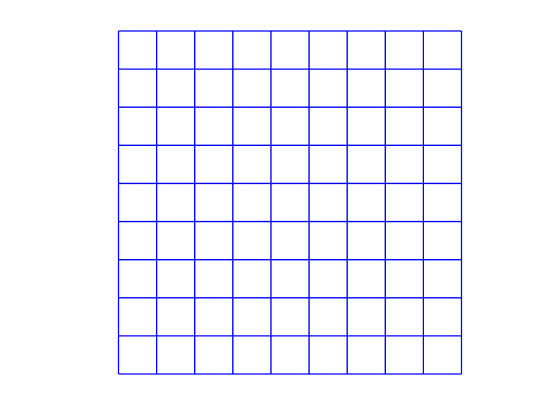

n = 10;
m = 10;
[x1, x2] = meshgrid(1:n, 1:m);
plotgrid(x1, x2);

Q = [ones(size(x1(:))) x1(:) x2(:)];
w = [0 0 0.2 0 0.2 0]';
y = [x1(:); x2(:)] + kron(eye(2), Q) * w;
y1 = reshape(y(1:end/2), n, m)

y1 =     1.2000    2.2000    3.2000    4.2000    5.2000    6.2000    7.2000    8.2000    9.2000   10.2000
    1.4000    2.4000    3.4000    4.4000    5.4000    6.4000    7.4000    8.4000    9.4000   10.4000
    1.6000    2.6000    3.6000    4.6000    5.6000    6.6000    7.6000    8.6000    9.6000   10.6000
    1.8000    2.8000    3.8000    4.8000    5.8000    6.8000    7.8000    8.8000    9.8000   10.8000
    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000
    2.2000    3.2000    4.2000    5.2000    6.2000    7.2000    8.2000    9.2000   10.2000   11.2000
    2.4000    3.4000    4.4000    5.4000    6.4000    7.4000    8.4000    9.4000   10.4000   11.4000
    2.6000    3.6000    4.6000    5.6000    6.6000    7.6000    8.6000    9.6000   10.6000   11.6000
    2.8000    3.8000    4.8000    5.8000    6.8000    7.8000    8.8000    9.8000   10.8000   11.8000
    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.

y2 = reshape(y((end/2 + 1):end), n, m)

y2 =     1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000
    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000
    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000
    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000
    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000
    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000
    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000
    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000   10.0000
    9.2000    9.4000    9.6000    9.8000   10.0000   10.2000   10.4000   10.6000   10.8000   11.0000
   10.2000   10.4000   10.6000   10.8000   11.0000   11.2000   11.4000   11.6000   11.

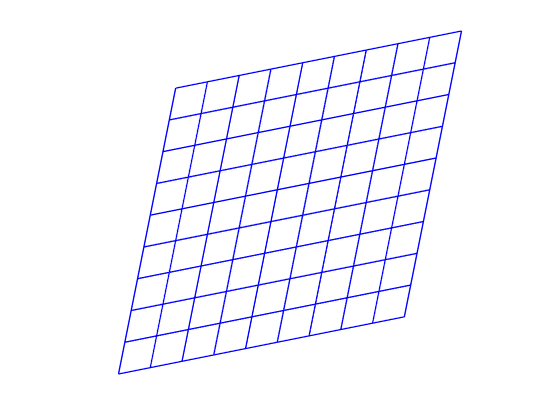


plotgrid(y1, y2);

%Generate the 2D spline functions

m = [31 31]

m =     31    31


p1 = 5; p2 = 5;
k1 = linspace(1, m(1), p1);
k1 = augknt(k1, 3);
k2 = linspace(1, m(2), p2);
k2 = augknt(k2, 3);
B1 = spmak(k1, eye(p1))

B1 = struct with fields:
      form: 'B-'
     knots: [1 1 1 8.5000 16 23.5000 31 31 31]
     coefs: [5×5 double]
    number: 5
     order: 4
       dim: 5


Q1 = fnval(B1, 1:m(1))'

Q1 =          0         0         0         0         0
    0.3241    0.0245    0.0004         0         0
    0.5132    0.0893    0.0032         0         0
    0.5920    0.1813    0.0107         0         0
    0.5855    0.2876    0.0253         0         0
    0.5185    0.3951    0.0494         0         0
    0.4160    0.4907    0.0853         0         0
    0.3028    0.5614    0.1355         0         0
    0.2033    0.5946    0.2021    0.0000         0
    0.1280    0.5880    0.2827    0.0013         0


B2 = spmak(k2, eye(p2));
Q2 = fnval(B2, 1:m(2))';
Q = kron(speye(2), kron(Q1, Q2))

Q =   (33,1)       0.1051
  (34,1)       0.1663
  (35,1)       0.1919
  (36,1)       0.1898
  (37,1)       0.1681
  (38,1)       0.1348
  (39,1)       0.0982
  (40,1)       0.0659
  (41,1)       0.0415
  (42,1)       0.0240
  (43,1)       0.0123
  (44,1)       0.0052
  (45,1)       0.0015
  (46,1)       0.0002
  (64,1)       0.1663
  (65,1)       0.2634
  (66,1)       0.3038
  (67,1)       0.3005
  (68,1)       0.2661
  (69,1)       0.2135
  (70,1)       0.1554
  (71,1)       0.1043
  (72,1)       0.0657
  (73,1)       0.0380
  (74,1)       0.0195
  (75,1)       0.0082
  (76,1)       0.0024
  (77,1)       0.0003
  (95,1)       0.1919
  (96,1)       0.3038
  (97,1)       0.3505
  (98,1)       0.3466
  (99,1)       0.3070
 (100,1)       0.2463
 (101,1)       0.1793
 (102,1)       0.1203
 (103,1)       0.0758
 (104,1)       0.0439
 (105,1)       0.0225
 (106,1)       0.0095
 (107,1)       0.0028
 (108,1)       0.0004
 (126,1)       0.1898
 (127,1)       0.3005
 (128,1)       0.3466
 (129,


[x1, x2] = meshgrid(1:m(2), 1:m(1))

x1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10

x2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6

size(Q)

ans =         1922          50


y = [x1(:), x2(:)] + Q * w * 0.4

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation